The provided code accomplishes the following:

- It defines the path to the dataset folder.

- It reads the train dataset from a CSV file located in the dataset folder.

- It reads the test dataset from a CSV file located in the dataset folder.

- It separates the features and labels in the train and test dataset.

% Specify the path to the dataset folder
datasetPath = 'dataset/';

% Import the train dataset
trainData = readtable(fullfile(datasetPath, 'train.csv'));


% Import the test dataset
testData = readtable(fullfile(datasetPath, 'test.csv'));


% Separate the features and labels in the train dataset
trainFeatures = trainData(:, 1:end-1);
trainLabels = trainData.Activity;

% Separate the features and labels in the test dataset
testLabels = testData.Activity;
testFeatures = testData(:, 1:end-1);

% Call the preprocessData function
[trainFeatures, testFeatures] = preprocessFeatures(trainFeatures, testFeatures);

Data Visualization: Balanced class distribution, good for modeling.

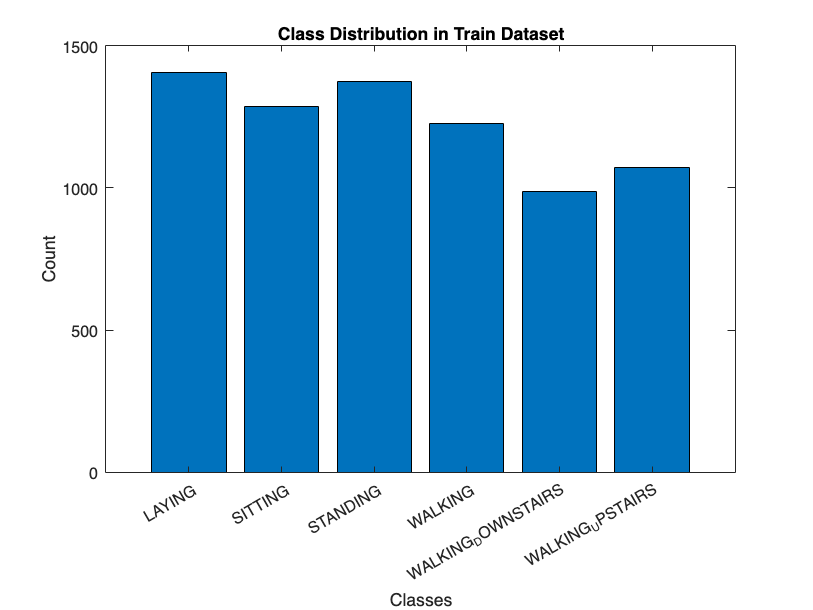

% Plot class distribution for train dataset
plotClassDistribution(trainLabels, 'Class Distribution in Train Dataset');

Define all different models for experimentation

% Define different classifier models
classifierModels = cell(1, 10);
classifierModels{1} = fitctree(trainFeatures{:,:}, trainLabels); % Decision Tree
classifierModels{2} = fitcknn(trainFeatures{:,:}, trainLabels); % k-Nearest Neighbors
classifierModels{3} = fitcecoc(trainFeatures{:,:}, trainLabels); % Error-Correcting Output Codes
classifierModels{4} = fitcnb(trainFeatures{:,:}, trainLabels); % Naive Bayes
classifierModels{5} = fitcecoc(trainFeatures{:,:}, trainLabels); % Support Vector Machine
classifierModels{6} = fitcdiscr(trainFeatures{:,:}, trainLabels); % Discriminant Analysis

% Initialize variables for best accuracy
bestAccuracy = 0;
bestModelIndex = 0;
bestPredictedLabels = [];

% Initialize an array to store accuracies
accuracies = zeros(1, 10);

% Train and evaluate models
for i = 1:numel(classifierModels)
    % Use the trained model to predict labels for the test dataset
    predictedLabels = predict(classifierModels{i}, testFeatures{:,:});

    % Calculate the accuracy
    correctPredictions = sum(strcmp(predictedLabels, testLabels));
    accuracy = correctPredictions / numel(testLabels);
    
    % Store the accuracy in the array
    accuracies(i) = accuracy;
    
    % Display the accuracy
    disp(['Accuracy of Model ' num2str(i) ': ' num2str(accuracy)]);
    
    % Check if the current model has the best accuracy so far
    if accuracy > bestAccuracy
        bestAccuracy = accuracy;
        bestModelIndex = i;
        bestPredictedLabels = predictedLabels;
    end
end

Accuracy of Model 1: 0.86461
Accuracy of Model 2: 0.85477
Accuracy of Model 3: 0.95385
Accuracy of Model 4: 0.76994
Accuracy of Model 5: 0.95385
Accuracy of Model 6: 0.96301


Incorrect number or types of inputs or outputs for function 'predict'.

The `preprocessFeatures` function handles missing data by filling it with the median value and standardizes the feature data using z-score normalization. It returns the processed training and test feature data.

function [processedTrainFeatures, processedTestFeatures] = preprocessFeatures(trainFeatures, testFeatures)
    % Handle missing data
    processedTrainFeatures = fillmissing(trainFeatures, 'constant', nanmedian(trainFeatures.Variables));
    processedTestFeatures = fillmissing(testFeatures, 'constant', nanmedian(testFeatures.Variables));

    % Standardize data using z-score normalization
    mu = mean(processedTrainFeatures.Variables);
    sigma = std(processedTrainFeatures.Variables);

    processedTrainFeatures.Variables = (processedTrainFeatures.Variables - mu) ./ sigma;
    processedTestFeatures.Variables = (processedTestFeatures.Variables - mu) ./ sigma;
end


Function that shows the distribution of data across different classes.

% Function to plot the distribution of classes
function plotClassDistribution(labels, titleName)
    categories = unique(labels);
    counts = countcats(categorical(labels));
    bar(categorical(categories), counts);
    title(titleName);
    xlabel('Classes');
    ylabel('Count');
end
